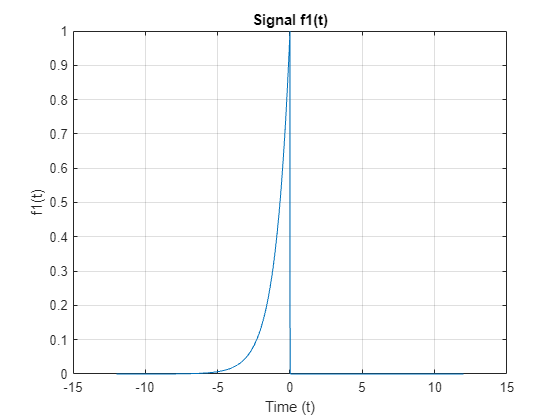

% time vector 
t = -12:0.01:12;

% signals s1(t), s2(t), and x(t)
s1 = @(t) exp(-t) .* (t >= 0);
s2 = @(t) (t + 1) .* ((t >= -1) & (t < 0)) + (1 - t) .* ((t >= 0) & (t <= 1));
x = @(t) (t + 4) .* ((t >= -5) & (t <= -1)) + 3 .* ((t > -1) & (t < 2)) + (7 - 2 .* t) .* ((t >= 2) & (t <= 5));

% signals f1(t), f2(t), and f3(t)
f1 = s1(-t);
f2 = s2(-t-1);
f3 = x(-t-2);

% plot f1(t)
figure;
plot(t, f1);
xlabel('Time (t)');
ylabel('f1(t)');
title('Signal f1(t)');
grid on;

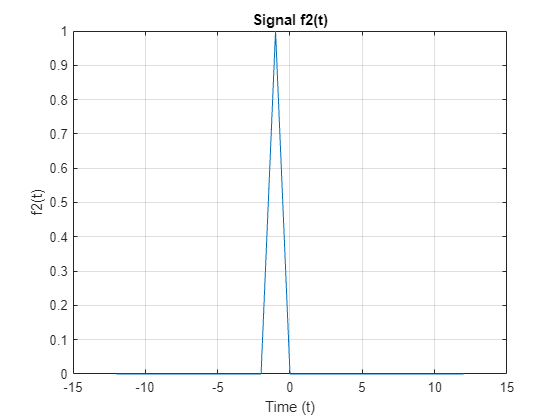


% plot f2(t)
figure;
plot(t, f2);
xlabel('Time (t)');
ylabel('f2(t)');
title('Signal f2(t)');
grid on;

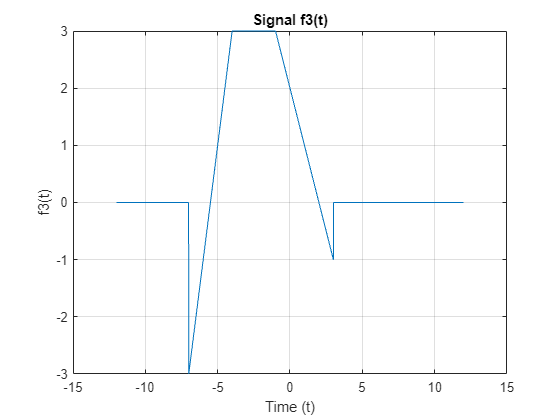


% plot f3(t)
figure;
plot(t, f3);
xlabel('Time (t)');
ylabel('f3(t)');
title('Signal f3(t)');
grid on;